**Generate Hopping Sequence for bluetooth channels**

Here, we define the **hopping sequence**. The carrier frequency hops between different values for each symbol.

% Parameters
numPeripherals = 12;             % Number of peripheral devices


% Define the channels with GFSK parameters
function channels = generateCarrierSignals(numChannels, symbolRate, Fs, BT, modulationIndex)
    % Initialize channels structure
    channels = struct([]);
    
    % Define the starting frequency for Bluetooth channels (in Hz)
    baseFrequency = 2400e6; % 2400 MHz

    for ch = 1:numChannels
        % Set channel parameters
        channels(ch).frequency = baseFrequency + (ch - 1) * 1e6;  % Start at 2400 MHz, increment by 1 MHz
        channels(ch).Fc = channels(ch).frequency;                 % Carrier frequency for each channel
        channels(ch).Fs = Fs;                                     % Sampling frequency for GFSK modulation
        channels(ch).BT = BT;                                     % Bandwidth-Time product
        channels(ch).symbolRate = symbolRate;                     % Symbol rate
        channels(ch).modulationIndex = modulationIndex;           % Modulation index

        % Generate binary data for testing (a random stream of 0s and 1s)
        numBits = 100;                                            % Number of bits to simulate
        data = randi([0 1], 1, numBits);

        % Upsample data to match the sampling frequency
        samplesPerSymbol = Fs / symbolRate;
        dataUpsampled = repelem(data, samplesPerSymbol);

        % Apply Gaussian filter to create a smoothed signal
        filterSpan = 4;                                           % Filter span in symbols
        t = linspace(-filterSpan / 2, filterSpan / 2, samplesPerSymbol * filterSpan);
        gaussianFilter = exp(-2 * (pi * BT * t).^2);
        filteredSignal = conv(dataUpsampled, gaussianFilter, 'same');
        
        % Create time vector for the carrier signal
        tVec = (0:length(filteredSignal) - 1) / Fs;

        % Generate GFSK-modulated carrier signal
        f0 = channels(ch).Fc - modulationIndex * symbolRate / 2;
        f1 = channels(ch).Fc + modulationIndex * symbolRate / 2;
        carrierSignal = cos(2 * pi * (f0 + (f1 - f0) * filteredSignal) .* tVec);

        % Store the generated carrier signal in the channels structure
        channels(ch).carrierSignal = carrierSignal;
    end
end

numChannels = 10;
symbolRate = 1e3;       % 1 kHz symbol rate
Fs = 1e6;               % Sampling frequency of 1 MHz
BT = 0.5;               % Bandwidth-time product
modulationIndex = 0.5;  % Modulation index

channels = generateCarrierSignals(numChannels, symbolRate, Fs, BT, modulationIndex);

% Define central node
centralNode.id = "Central";
centralNode.messageBuffer = {};                     % Buffer to store messages
centralNode.status = "Connected";
centralNode.position = [0, 0];                      % Position of the central node
centralNode.currentChannel = randi(numChannels);    % Initial random channel
centralNode.channel = channels(centralNode.currentChannel); % Initial GFSK channel

% Define peripheral nodes
peripheralNodes = struct([]);
for i = 1:numPeripherals
    peripheralNodes(i).id = "Peripheral_" + i;
    peripheralNodes(i).messageBuffer = {i};
    peripheralNodes(i).status = "Connected";
    peripheralNodes(i).position = [];
    peripheralNodes(i).currentChannel = randi(numChannels);  % Initial random channel
    peripheralNodes(i).channel = channels(peripheralNodes(i).currentChannel); % Initial GFSK channel
end

% Channel switching function
function node = switchChannel(node, channels)
    newChannelIndex = randi(numel(channels));       % Pick a new random channel
    node.currentChannel = newChannelIndex;          % Update the node's current channel index
    node.channel = channels(newChannelIndex);       % Update node's channel properties to new channel
end

for i = 1:numPeripherals
    
    peripheralNodes(i) = switchChannel(peripheralNodes(i), channels);
    
    
    currentChannel = peripheralNodes(i).currentChannel;
    
    % Sample carrier signal for display (e.g., first 5 samples)
    carrierSignalSample = channels(currentChannel).carrierSignal(1:5);
    
    % Display information
    disp([peripheralNodes(i).id ' switched to channel ' num2str(currentChannel) ...
          ' with frequency ' num2str(channels(currentChannel).frequency) ' Hz' ...
          ', BT product ' num2str(channels(currentChannel).BT) ...
          ', symbol rate ' num2str(channels(currentChannel).symbolRate) ' Hz' ...
          ', and carrier signal sample [' num2str(carrierSignalSample) ']']);
end

    "Peripheral_1"    " switched to channel "    "9"    " with frequency "    "2408000000"    " Hz"    ", BT product "    "0.5"    ", symbol rate "    "1000"    " Hz"    ", and carrier signal sample ["    "1     0.31003    -0.81142    -0.79981     0.34036"    "]"

    "Peripheral_2"    " switched to channel "    "8"    " with frequency "    "2407000000"    " Hz"    ", BT product "    "0.5"    ", symbol rate "    "1000"    " Hz"    ", and carrier signal sample ["    "1     0.30799    -0.81395    -0.79584     0.34868"    "]"

    "Peripheral_3"    " switched to channel "    "6"    " with frequency "    "2405000000"    " Hz"    ", BT product "    "0.5"    ", symbol rate "    "1000"    " Hz"    ", and carrier signal sample ["    "1     0.30799    -0.81395    -0.79584     0.34868"    "]"

    "Peripheral_4"    " switched to channel "    "2"    " with frequency "    "2401000000"    " Hz"    ", BT product "    "0.5"    ", symbol rate "    "1000"    " Hz"    ", and carrier signal sample ["    


%Figure of 1 channel of 1 node
chosenPeripheral = 1;
currentChannel = peripheralNodes(chosenPeripheral).currentChannel;
carrierSignal = channels(currentChannel).carrierSignal;
symbolRate = channels(currentChannel).symbolRate;
BT = channels(currentChannel).BT;


span = 6;   
sps = channels(currentChannel).Fs / symbolRate;  
gaussianFilter = gaussdesign(BT, span, sps);  %


filteredCarrierSignal = conv(carrierSignal, gaussianFilter, 'same');

% Plot Gaussian Filter Response
figure;
subplot(2, 1, 1);

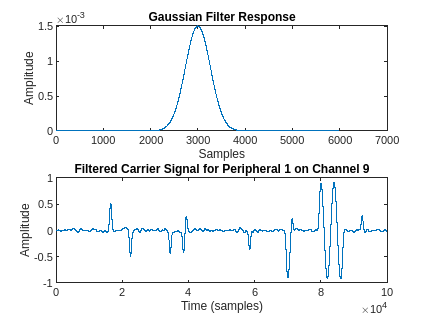

plot(gaussianFilter);
title('Gaussian Filter Response');
xlabel('Samples');
ylabel('Amplitude');

% Plot Filtered Carrier Signal
subplot(2, 1, 2);
plot(filteredCarrierSignal);
title(['Filtered Carrier Signal for Peripheral ' num2str(chosenPeripheral) ...
       ' on Channel ' num2str(currentChannel)]);
xlabel('Time (samples)');
ylabel('Amplitude');

**Define parameters for construction of bluetooth star topology**

% Parameters
numRounds = 5;                  % Number of communication rounds
hopRate = 1600;                 % Frequency hop rate in hops per second (simulated)
fs = 1/hopRate;                 % Time step to simulate hops

**Define nodes**

% Visualization
figure;
hold on;
theta1 = linspace(pi/4, 3*pi/4, numPeripherals/2); % Angles for the first hand (left)
theta2 = linspace(5*pi/4, 7*pi/4, numPeripherals/2); % Angles for the second hand

% Radius for nodes
r = 1.5; % Radius from the central node

% Plot central node
plot(0, 0, 'ro', 'MarkerSize', 10, 'DisplayName', 'Central Node');
text(0, 0, 'Central', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');

% Plot peripheral nodes for the left hand
for i = 1:numPeripherals/2
    x = r * cos(theta1(i));
    y = r * sin(theta1(i));
    peripheralNodes(i).position = [x, y]; % Store position
    plot(x, y, 'bo', 'MarkerSize', 8, 'DisplayName', peripheralNodes(i).id);
    text(x, y, peripheralNodes(i).id, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
    line([0 x], [0 y], 'Color', 'k', 'LineStyle', '--'); % Connection line to central node
end

% Plot peripheral nodes for the right hand
for i = (numPeripherals/2 + 1):numPeripherals
    x = r * cos(theta2(i - numPeripherals/2)); % Adjust index for the second half
    y = r * sin(theta2(i - numPeripherals/2));
    j = ceil(i)
    peripheralNodes(j).position = [x, y]; % Store position
    plot(x, y, 'bo', 'MarkerSize', 8, 'DisplayName', peripheralNodes(j).id);
    text(x, y, peripheralNodes(j).id, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
    line([0 x], [0 y], 'Color', 'k', 'LineStyle', '--'); % Connection line to central node
end

j = 7

j = 8

j = 9

j = 10

j = 11

j = 12

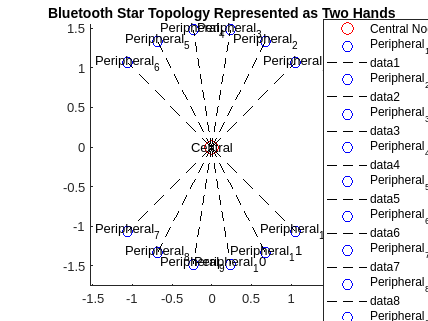


% Adjust axes and title
axis equal;
axis([-2 2 -2 2]); % Set axis limits for better visualization
title("Bluetooth Star Topology Represented as Two Hands");
legend show;
hold off;


% Frequency hopping and message simulation
for t = 1:numRounds
    fprintf('\nRound %d - Frequency Hopping\n', t);
    
    % Central and peripherals hop to a new channel

    centralNode = switchChannel(centralNode, channels);
    disp([centralNode.id ' switched to channel ' num2str(centralNode.currentChannel) ...
              ' with frequency ' num2str(centralNode.channel.frequency) ' Hz' ...
              ', BT product ' num2str(centralNode.channel.BT) ...
              ', and symbol rate ' num2str(centralNode.channel.symbolRate) ' Hz']);
    % Each peripheral hops to a new channel
    for i = 1:numPeripherals
        peripheralNodes(i) = switchChannel(peripheralNodes(i), channels);
        disp([peripheralNodes(i).id ' switched to channel ' num2str(peripheralNodes(i).currentChannel) ...
              ' with frequency ' num2str(peripheralNodes(i).channel.frequency) ' Hz' ...
              ', BT product ' num2str(peripheralNodes(i).channel.BT) ...
              ', and symbol rate ' num2str(peripheralNodes(i).channel.symbolRate) ' Hz']);
    end
    % Data transmission attempt
    for i = 1:numPeripherals
        if centralNode.currentChannel == peripheralNodes(i).currentChannel
            % Central sends a message if on the same channel as peripheral
            messageToPeripheral = "Message from Central to " + peripheralNodes(i).id + " at round " + t;
            peripheralNodes(i).messageBuffer{end+1} = messageToPeripheral;
            disp("Central sent to " + peripheralNodes(i).id + ": " + messageToPeripheral);
            
            % Peripheral responds back if on the same channel
            messageToCentral = "Response from " + peripheralNodes(i).id + " at round " + t;
            centralNode.messageBuffer{end+1} = messageToCentral;
            disp(peripheralNodes(i).id + " sent to Central: " + messageToCentral);
        else
            % No communication if channels don't match
            disp(peripheralNodes(i).id + " and Central are on different channels, no message exchanged.");
        end
    end
    
    % Optional: Display message buffers after each round
    disp("Central Node Message Buffer: ");
    disp(centralNode.messageBuffer);
    for i = 1:numPeripherals
        disp(peripheralNodes(i).id + " Message Buffer: ");
        disp(peripheralNodes(i).messageBuffer);
    end
    
    % Pause to simulate delay between rounds
    pause(1); % Simulation delay for visual effect
end


Round 1 - Frequency Hopping


    "Central"    " switched to channel "    "1"    " with frequency "    "2400000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"



    "Peripheral_1"    " switched to channel "    "8"    " with frequency "    "2407000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_2"    " switched to channel "    "4"    " with frequency "    "2403000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_3"    " switched to channel "    "7"    " with frequency "    "2406000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_4"    " switched to channel "    "4"    " with frequency "    "2403000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_5"    " switched to channel "    "7"    " with frequency "    "2406000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_6"    " switched to channel "    "1"    " with frequency "    "2400000000"    " Hz"    ", BT product "    "0.5"    ", and sy

Peripheral_1 and Central are on different channels, no message exchanged.
Peripheral_2 and Central are on different channels, no message exchanged.
Peripheral_3 and Central are on different channels, no message exchanged.
Peripheral_4 and Central are on different channels, no message exchanged.
Peripheral_5 and Central are on different channels, no message exchanged.


Central sent to Peripheral_6: Message from Central to Peripheral_6 at round 1


Peripheral_6 sent to Central: Response from Peripheral_6 at round 1


Peripheral_7 and Central are on different channels, no message exchanged.
Peripheral_8 and Central are on different channels, no message exchanged.
Peripheral_9 and Central are on different channels, no message exchanged.
Peripheral_10 and Central are on different channels, no message exchanged.
Peripheral_11 and Central are on different channels, no message exchanged.
Peripheral_12 and Central are on different channels, no message exchanged.


Central Node Message Buffer: 


    {["Response from Peripheral_6 at round 1"]}



Peripheral_1 Message Buffer: 


    {[1]}



Peripheral_2 Message Buffer: 


    {[2]}



Peripheral_3 Message Buffer: 


    {[3]}



Peripheral_4 Message Buffer: 


    {[4]}



Peripheral_5 Message Buffer: 


    {[5]}



Peripheral_6 Message Buffer: 


    {[6]}    {["Message from Central to Peripheral_6 at round 1"]}



Peripheral_7 Message Buffer: 


    {[7]}



Peripheral_8 Message Buffer: 


    {[8]}



Peripheral_9 Message Buffer: 


    {[9]}



Peripheral_10 Message Buffer: 


    {[10]}



Peripheral_11 Message Buffer: 


    {[11]}



Peripheral_12 Message Buffer: 


    {[12]}




Round 2 - Frequency Hopping


    "Central"    " switched to channel "    "6"    " with frequency "    "2405000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"



    "Peripheral_1"    " switched to channel "    "6"    " with frequency "    "2405000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_2"    " switched to channel "    "3"    " with frequency "    "2402000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_3"    " switched to channel "    "3"    " with frequency "    "2402000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_4"    " switched to channel "    "5"    " with frequency "    "2404000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_5"    " switched to channel "    "3"    " with frequency "    "2402000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_6"    " switched to channel "    "9"    " with frequency "    "2408000000"    " Hz"    ", BT product "    "0.5"    ", and sy

Central sent to Peripheral_1: Message from Central to Peripheral_1 at round 2


Peripheral_1 sent to Central: Response from Peripheral_1 at round 2


Peripheral_2 and Central are on different channels, no message exchanged.
Peripheral_3 and Central are on different channels, no message exchanged.
Peripheral_4 and Central are on different channels, no message exchanged.
Peripheral_5 and Central are on different channels, no message exchanged.
Peripheral_6 and Central are on different channels, no message exchanged.
Peripheral_7 and Central are on different channels, no message exchanged.
Peripheral_8 and Central are on different channels, no message exchanged.


Central sent to Peripheral_9: Message from Central to Peripheral_9 at round 2


Peripheral_9 sent to Central: Response from Peripheral_9 at round 2


Peripheral_10 and Central are on different channels, no message exchanged.
Peripheral_11 and Central are on different channels, no message exchanged.
Peripheral_12 and Central are on different channels, no message exchanged.


Central Node Message Buffer: 


    {["Response from Peripheral_6 at round 1"]}    {["Response from Peripheral_1 at round 2"]}    {["Response from Peripheral_9 at round 2"]}



Peripheral_1 Message Buffer: 


    {[1]}    {["Message from Central to Peripheral_1 at round 2"]}



Peripheral_2 Message Buffer: 


    {[2]}



Peripheral_3 Message Buffer: 


    {[3]}



Peripheral_4 Message Buffer: 


    {[4]}



Peripheral_5 Message Buffer: 


    {[5]}



Peripheral_6 Message Buffer: 


    {[6]}    {["Message from Central to Peripheral_6 at round 1"]}



Peripheral_7 Message Buffer: 


    {[7]}



Peripheral_8 Message Buffer: 


    {[8]}



Peripheral_9 Message Buffer: 


    {[9]}    {["Message from Central to Peripheral_9 at round 2"]}



Peripheral_10 Message Buffer: 


    {[10]}



Peripheral_11 Message Buffer: 


    {[11]}



Peripheral_12 Message Buffer: 


    {[12]}




Round 3 - Frequency Hopping


    "Central"    " switched to channel "    "1"    " with frequency "    "2400000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"



    "Peripheral_1"    " switched to channel "    "10"    " with frequency "    "2409000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_2"    " switched to channel "    "1"    " with frequency "    "2400000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_3"    " switched to channel "    "7"    " with frequency "    "2406000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_4"    " switched to channel "    "8"    " with frequency "    "2407000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_5"    " switched to channel "    "6"    " with frequency "    "2405000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_6"    " switched to channel "    "9"    " with frequency "    "2408000000"    " Hz"    ", BT product "    "0.5"    ", and s

Peripheral_1 and Central are on different channels, no message exchanged.


Central sent to Peripheral_2: Message from Central to Peripheral_2 at round 3


Peripheral_2 sent to Central: Response from Peripheral_2 at round 3


Peripheral_3 and Central are on different channels, no message exchanged.
Peripheral_4 and Central are on different channels, no message exchanged.
Peripheral_5 and Central are on different channels, no message exchanged.
Peripheral_6 and Central are on different channels, no message exchanged.
Peripheral_7 and Central are on different channels, no message exchanged.
Peripheral_8 and Central are on different channels, no message exchanged.
Peripheral_9 and Central are on different channels, no message exchanged.
Peripheral_10 and Central are on different channels, no message exchanged.
Peripheral_11 and Central are on different channels, no message exchanged.


Central sent to Peripheral_12: Message from Central to Peripheral_12 at round 3


Peripheral_12 sent to Central: Response from Peripheral_12 at round 3


Central Node Message Buffer: 


    {["Response from Peripheral_6 at round 1"]}    {["Response from Peripheral_1 at round 2"]}    {["Response from Peripheral_9 at round 2"]}    {["Response from Peripheral_2 at round 3"]}    {["Response from Peripheral_12 at round 3"]}



Peripheral_1 Message Buffer: 


    {[1]}    {["Message from Central to Peripheral_1 at round 2"]}



Peripheral_2 Message Buffer: 


    {[2]}    {["Message from Central to Peripheral_2 at round 3"]}



Peripheral_3 Message Buffer: 


    {[3]}



Peripheral_4 Message Buffer: 


    {[4]}



Peripheral_5 Message Buffer: 


    {[5]}



Peripheral_6 Message Buffer: 


    {[6]}    {["Message from Central to Peripheral_6 at round 1"]}



Peripheral_7 Message Buffer: 


    {[7]}



Peripheral_8 Message Buffer: 


    {[8]}



Peripheral_9 Message Buffer: 


    {[9]}    {["Message from Central to Peripheral_9 at round 2"]}



Peripheral_10 Message Buffer: 


    {[10]}



Peripheral_11 Message Buffer: 


    {[11]}



Peripheral_12 Message Buffer: 


    {[12]}    {["Message from Central to Peripheral_12 at round 3"]}




Round 4 - Frequency Hopping


    "Central"    " switched to channel "    "2"    " with frequency "    "2401000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"



    "Peripheral_1"    " switched to channel "    "7"    " with frequency "    "2406000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_2"    " switched to channel "    "10"    " with frequency "    "2409000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_3"    " switched to channel "    "4"    " with frequency "    "2403000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_4"    " switched to channel "    "5"    " with frequency "    "2404000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_5"    " switched to channel "    "10"    " with frequency "    "2409000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_6"    " switched to channel "    "10"    " with frequency "    "2409000000"    " Hz"    ", BT product "    "0.5"    ", and

Peripheral_1 and Central are on different channels, no message exchanged.
Peripheral_2 and Central are on different channels, no message exchanged.
Peripheral_3 and Central are on different channels, no message exchanged.
Peripheral_4 and Central are on different channels, no message exchanged.
Peripheral_5 and Central are on different channels, no message exchanged.
Peripheral_6 and Central are on different channels, no message exchanged.
Peripheral_7 and Central are on different channels, no message exchanged.
Peripheral_8 and Central are on different channels, no message exchanged.
Peripheral_9 and Central are on different channels, no message exchanged.
Peripheral_10 and Central are on different channels, no message exchanged.
Peripheral_11 and Central are on different channels, no message exchanged.
Peripheral_12 and Central are on different channels, no message exchanged.


Central Node Message Buffer: 


    {["Response from Peripheral_6 at round 1"]}    {["Response from Peripheral_1 at round 2"]}    {["Response from Peripheral_9 at round 2"]}    {["Response from Peripheral_2 at round 3"]}    {["Response from Peripheral_12 at round 3"]}



Peripheral_1 Message Buffer: 


    {[1]}    {["Message from Central to Peripheral_1 at round 2"]}



Peripheral_2 Message Buffer: 


    {[2]}    {["Message from Central to Peripheral_2 at round 3"]}



Peripheral_3 Message Buffer: 


    {[3]}



Peripheral_4 Message Buffer: 


    {[4]}



Peripheral_5 Message Buffer: 


    {[5]}



Peripheral_6 Message Buffer: 


    {[6]}    {["Message from Central to Peripheral_6 at round 1"]}



Peripheral_7 Message Buffer: 


    {[7]}



Peripheral_8 Message Buffer: 


    {[8]}



Peripheral_9 Message Buffer: 


    {[9]}    {["Message from Central to Peripheral_9 at round 2"]}



Peripheral_10 Message Buffer: 


    {[10]}



Peripheral_11 Message Buffer: 


    {[11]}



Peripheral_12 Message Buffer: 


    {[12]}    {["Message from Central to Peripheral_12 at round 3"]}




Round 5 - Frequency Hopping


    "Central"    " switched to channel "    "3"    " with frequency "    "2402000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"



    "Peripheral_1"    " switched to channel "    "7"    " with frequency "    "2406000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_2"    " switched to channel "    "6"    " with frequency "    "2405000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_3"    " switched to channel "    "5"    " with frequency "    "2404000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_4"    " switched to channel "    "7"    " with frequency "    "2406000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_5"    " switched to channel "    "8"    " with frequency "    "2407000000"    " Hz"    ", BT product "    "0.5"    ", and symbol rate "    "1000"    " Hz"

    "Peripheral_6"    " switched to channel "    "6"    " with frequency "    "2405000000"    " Hz"    ", BT product "    "0.5"    ", and sy

Peripheral_1 and Central are on different channels, no message exchanged.
Peripheral_2 and Central are on different channels, no message exchanged.
Peripheral_3 and Central are on different channels, no message exchanged.
Peripheral_4 and Central are on different channels, no message exchanged.
Peripheral_5 and Central are on different channels, no message exchanged.
Peripheral_6 and Central are on different channels, no message exchanged.
Peripheral_7 and Central are on different channels, no message exchanged.
Peripheral_8 and Central are on different channels, no message exchanged.
Peripheral_9 and Central are on different channels, no message exchanged.
Peripheral_10 and Central are on different channels, no message exchanged.
Peripheral_11 and Central are on different channels, no message exchanged.
Peripheral_12 and Central are on different channels, no message exchanged.


Central Node Message Buffer: 


    {["Response from Peripheral_6 at round 1"]}    {["Response from Peripheral_1 at round 2"]}    {["Response from Peripheral_9 at round 2"]}    {["Response from Peripheral_2 at round 3"]}    {["Response from Peripheral_12 at round 3"]}



Peripheral_1 Message Buffer: 


    {[1]}    {["Message from Central to Peripheral_1 at round 2"]}



Peripheral_2 Message Buffer: 


    {[2]}    {["Message from Central to Peripheral_2 at round 3"]}



Peripheral_3 Message Buffer: 


    {[3]}



Peripheral_4 Message Buffer: 


    {[4]}



Peripheral_5 Message Buffer: 


    {[5]}



Peripheral_6 Message Buffer: 


    {[6]}    {["Message from Central to Peripheral_6 at round 1"]}



Peripheral_7 Message Buffer: 


    {[7]}



Peripheral_8 Message Buffer: 


    {[8]}



Peripheral_9 Message Buffer: 


    {[9]}    {["Message from Central to Peripheral_9 at round 2"]}



Peripheral_10 Message Buffer: 


    {[10]}



Peripheral_11 Message Buffer: 


    {[11]}



Peripheral_12 Message Buffer: 


    {[12]}    {["Message from Central to Peripheral_12 at round 3"]}

